# ASSIGNMENT 4

Gianpaolo Mastroiacovo(ge28tud)

Antonio Di Giovanni(03743324)

Date(18/05/2021)

## Exercise 4.1)

#### *a)*

Constraint (2) enforces the departures from every location, except for the depot $\left(\forall \;\;i:1\le i\le N\right)$, to be exactly one, as the sum of each row over all of the column has to be equal to 1. Constraint (1), instead, enforces the number of departures from a whatever location to be equal to the number of arrivals in that same location, i. e. one for every customer, as per constraint (2), but any value $1\le z\le N$for the depot.

#### *b)*

Constraint $\left(4\right)$ ensures that the quantity delivered to each customer is positive and not larger than the maximum capacity of the vehicle $\bar{V}$: If for a given customer $x_{i,j} =0$, the right-hand side constraint $\left(5\right)$takes value 0, forcing $q_{i,j}$ to be $\le 0$. At the same time, $\left(4\right)$ forces this quantity to be non negative $\left(q_{i,j} \ge 0\right)$,  that makes it exactly $0$. Similarly, if $x_{i,j} =1$, according to $\left(5\right)$, $q_{i,j}$ could take any value between 0 and $M$(which is larger than the optimal $\bar{V}$), in this case$\left(4\right)$ makes sure the maximum value assumed by $q_{i,j}$ is $\bar{V}$.

#### *c)*

In constraint $\left(3\right)$, the difference between the cumulative delivered quantity after leaving a certain customer $i$ (going towards customer $j$) and the cumulative delivered quantity before reaching the same customer $i$ (coming from customer $k$), is set to be equal to the demand of customer $i$. This implies that the quantity delivered to that customer $i$ in that trip is exactly the demand of $i$, i. e. the demand of customer $i$ is satisfied all at once. That is, when moving from customer $i$ to customer $j$, if $x_{i,j} =1$, $q_{i,j}$ will include $d_i$ plus the demands of the previously served customers (in that trip). As demands are all positive, $q_{i,j}$ will certainly be at least equal to or larger than $q_{k,i}$ (with $k$ being the customer served before $i$).

#### *d)*

*Constraint *$\left(3\right)$ forces $q_{i,j}$ to be equal to the $q$ of the previously served customer minus the demand of the previous customer. When all of the demands of the customers that still have to be served are larger than the "remaining" $q_{i,j}$, and since $q_{i,j}$ cannot assume negative values because of $\left(8\right)$, the only possible choice is to go back to the deposit ($\left(3\right)$is only applied $\forall \;\;i:1\le i\le N$, i.e. not for the deposit). 

## Exercise 4.2)

#### *a)*

We will look for a solution with a maximum gap of 20% from the optimal one, as the solver takes several minutes to find the optimal solution on our computers.

clear;
load data_4.2.mat


N=length(customer_demands);
Capacity = intvar(1);
M=100;
N=length(customer_demands);
x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full');
distances = [N+1,N+1];

for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];
Cons = [Cons, sum(q(2:end,:),2) - sum(q(:,2:end),1)' == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];
Cons = [Cons, Capacity >= 0];

obj = vehicle_cost * Capacity +  (travel_cost * sum(distances .* x,"all"));

%ops = sdpsettings('solver', 'gurobi', 'verbose', 0);
ops = sdpsettings ('solver','gurobi', 'gurobi.MIPGap',0.2, 'verbose', 0);


Result = optimize(Cons, obj, ops);
value(obj)
value(x)

#### *b)*

scatter(locations(:,1),locations(:,2));
hold on 

ans = 8.6964

for i=1:N+1

ans =      1     1     0     0     0     0     0     1     0     0     0     1     0     1     0     1
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0


    for j=1:N+1
        if(value(x(i,j))==1)    
            plot(locations([i,j],1),locations([i,j],2),"Color",'b');
        end
    end
end
hold off

In the next section, we discuss how the route and the optimal vehicle size change when varying $c^V$ from its nominal value:

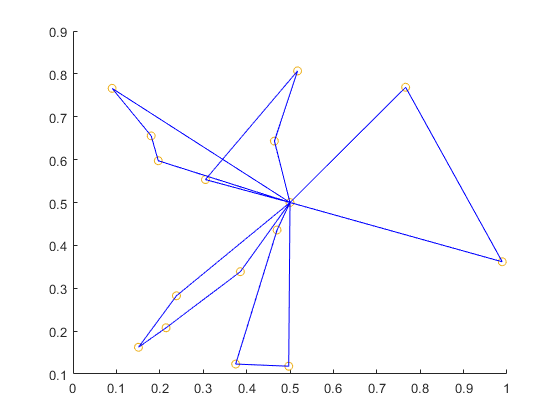

clear;

load data_4.2.mat


N=length(customer_demands);
x4_2b = zeros(N+1,N+1,6);
q4_2b = zeros(N+1,N+1,6);
Capacity4_2b = [];
m=0;
l_list = [];
for l=0:0.1:0.5
vehicle_cost = l; 
l_list = [l_list, l];
m=m+1;
Capacity = intvar(1);
M=100;
N=length(customer_demands);
x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full');
distances = [N+1,N+1];

for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];
Cons = [Cons, sum(q(2:end,:),2) - sum(q(:,2:end),1)' == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];
Cons = [Cons, Capacity >= 0];

obj = vehicle_cost * Capacity +  (travel_cost * sum(distances .* x,"all"));

%ops = sdpsettings('solver', 'gurobi', 'verbose', 0);
ops = sdpsettings ('solver','gurobi', 'gurobi.MIPGap',0.2, 'verbose', 0);


Result = optimize(Cons, obj, ops);

    Capacity4_2b = [Capacity4_2b, value(Capacity)];
    x4_2b(:,:,m) = value(x);
    q4_2b(:,:,m) = value(q);
end
l_list
Capacity4_2b
x4_2b
q4_2b

l_list =          0    0.1000    0.2000    0.3000    0.4000    0.5000


The vehicle size decreases as $c^V$ increases: 

- It reaches its minimum and remains constant from $c^V =0\ldotp 4$, so that it is possible to satisfy the maximum of the demands with one trip, thus increasing the number of trips and decreasing the number of customers served per trip.

- On the other hand, the vehicle size reaches its maximum when $c^V =0$, in our case, this size equals 90, as it is capped by the big-M constraint, in case this number was increased, the optimal solution would be to deliver all packages in one trip, and thus choose a vehicle size that is equal to the sum of all the demands.

#### *c)*

We will seek a solution with a maximum gap of 20% from the optimal one, as the solver takes several minutes to find an optimal solution on our computers.

load data_4.2.mat

Capacity4_2b =     90    36    26    26    16    16


x4_2b = x4_2b(:,:,1) =

     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0

cTau = [];

q4_2b = q4_2b(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   84.1836         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0   12.5432         0         0         0         0
         0         0         0         0         0         0         0   13.5198         0         0         0         0         0         0         0         0
         0         0         0         0         0   40.9612         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0   49.2189         0         0         0         0         0
   89.1091

nTravels = [];
objective = [];
Capacities = [];
for l=0:0.05:1
Capacity = intvar(1);
T = intvar(1);
M=100;
N=length(customer_demands);
x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full');
distances = [N+1,N+1];

for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];
Cons = [Cons, sum(q(2:end,:),2) - sum(q(:,2:end),1)' == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];
Cons = [Cons, T == sum(x(1,:),2)];


c_tau = l;

obj = vehicle_cost * Capacity +  (travel_cost * sum(distances .* x,"all") + c_tau*T);

%ops = sdpsettings('solver', 'gurobi', 'verbose', 0);
ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.2, 'verbose',0);


Result = optimize(Cons, obj, ops);

cTau = [cTau, c_tau];
nTravels = [nTravels, T];
objective = [objective, value(obj)];
Capacities = [Capacities, Capacity];
end


Interrupt request received

Interrupt request received


A =  [];
A(:,1) = value(cTau)';
A(:,2) = value(nTravels)';
A(:,3) = value(Capacities)';
A(:,4) = value(objective)';
A

A =          0    8.0000   26.0000    8.4845
    0.0500    7.0000   26.0000    8.8276
    0.1000    5.0000   41.0000    9.4121
    0.1500    5.0000   36.0000    9.3539
    0.2000    5.0000   36.0000    9.5935
    0.2500    5.0000   36.0000    9.8435
    0.3000    5.0000   36.0000   10.0935
    0.3500    5.0000   36.0000   10.3435
    0.4000    5.0000   36.0000   10.6964
    0.4500    4.0000   49.0000   10.8809


value(cTau)

ans =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


value(nTravels)

ans =     8.0000    7.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    4.0000    5.0000    4.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000


value(objective)

ans =     8.4845    8.8276    9.4121    9.3539    9.5935    9.8435   10.0935   10.3435   10.6964   10.8809   11.1014   11.2809   11.3256   11.4756   11.6256   11.7756   11.9256   12.0756   12.2256   12.3756   12.5256


value(Capacities)

ans =     26    26    41    36    36    36    36    36    36    49    36    49    56    56    56    56    56    56    56    56    56


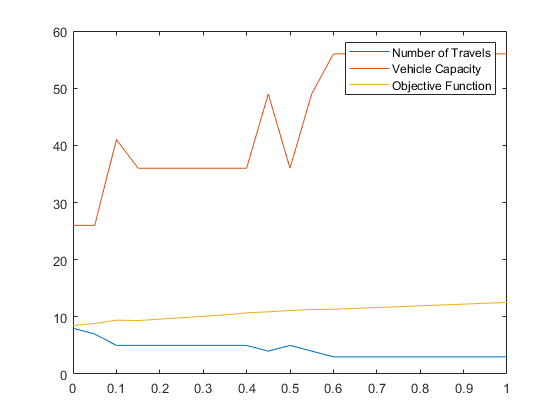

plot(value(cTau),value(nTravels),'DisplayName','Number of Travels')
hold on
plot(value(cTau),value(Capacities),'DisplayName',"Vehicle Capacity")
plot(value(cTau),value(objective),'DisplayName','Objective Function')
legend
ylim([0 60])
hold off

As $c^{\tau }$ increases, the value of the objective function clearly increases because of a higher "tax" to be paid. Moreover, as such fixed cost per trip increases, we notice that it's more convienent to reduce the number of trips and increase the capacity of the vehicle (being the cost per vehicles fixed), so that more customers can be served within the same trip. In addition, we notice that after a certain threshold (c.a. 0.6),  the two values (vehicle capacity and number of travels) become constant, since a further reduction of the number of trips would require a substantial increase of the vehicle size, such that the overall value of the objective function would end up being higher. (of course for high values of $c^{\tau \;}$ this statement would not be valid anymore, but in that case the cost per trip would not be of the same magnitude as the others, hence we don't consider such values).

## Exercise 4.3)

#### *a)*


$$\begin{array}{l}
\min_{x,\bar{V} ,q} \;\;\;\;\;c^V \bar{V} +S^{-1} \sum_{s\;\in \;S} \left.{\left(c\right.}^T {\left\|l_i -l_j \right\|}_2 x_{i\ldotp j}^s +c^{\tau \;} T^s \right)\\
\\
s\ldotp t\ldotp \;\;\;\\
\sum_{j=0}^N {x^s }_{i,j} \;=\sum_{k=0}^N {x^s }_{k,i} \;\;\;\;\;\;\;\forall i:0\le i\le N,\forall s\in S\\
\sum_{j=0}^N {x^s }_{i,j} =0\;\;\;\;\;\;\;\;\forall i:1\le i\le N,\forall s\in S\\
\sum_{j=0}^N {q^s }_{i,j} -\sum_{k=0}^N {q^s }_{k,i} ={d^s }_i \;\;\;\;\;\;\forall i:1\le i\le N,\;\forall s\in S\\
0\le q_{i,j}^s \le \bar{V} \;\;\;\;\;\;\;\;\;\forall i,j:0\le i,j\le N,\forall s\in S\\
q_{i,j}^s \le x_{i,j}^s M\;\;\;\;\;\;\;\;\;\;\;\forall i,j:0\le i,j\le N\ldotp \forall s\in S\\
x_{i,j}^s \in \left\lbrace 0,1\right\rbrace \;\;\;\;\;\;\;\;\;\;\forall i,j:0\le i,j\le N\ldotp \forall s\in S\\
T^s \ge 0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\forall s\in S\\
\bar{V} \in \aleph \\

\end{array}$$


#### *b)*

In this formulation, we assume the cost per unit of distance travelled between locations to be $=1$, as in the problem 4.2**, **thus the part of the cost proportional to the distance is not multiplied by a constant in the following objective function.

clear;
load data_4.3.mat

[N,S] = size(demand_scen);
Capacity = intvar(1);
T = intvar(1,S,'full');
M=100;
x = binvar(N+1,N+1,S, 'full'); 
q = sdpvar(N+1,N+1,S, 'full'); 
distances = [N+1,N+1];

for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

Cons = [];
for s=1:S
Cons = [Cons, sum(x(:,:,s),2) == transpose(sum(x(:,:,s),1))];
Cons = [Cons, sum(x(2:end,:,s),2) == 1];
Cons = [Cons, sum(q(2:end,:,s),2) - sum(q(:,2:end,s),1)' == demand_scen(:,s)];
Cons = [Cons, q(:,:,s) >= 0];
Cons = [Cons, q(:,:,s) <= Capacity];
Cons = [Cons, q(:,:,s) <= x(:,:,s) .* M];
Cons = [Cons, T(:,s) == sum(x(1,:,s),2)];
end
Cons = [Cons, Capacity >= 0];
Cons=[Cons, T>=0];

% Transform distance matrix from 10x10 to 10x10x10
for i=1:S
    distances(:,:,i) = distances(:,:,1);
end

obj = vehicle_cost * Capacity +  mean(squeeze(sum(sum(distances .* x,1),2))' + fixed_tour_cost .* T);


ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.2, 'verbose', 0);
Result = optimize(Cons, obj, ops);
StocObjective = value(obj)

StocObjective = 12.9085

StocCapacity = value(Capacity)

StocCapacity = 17

#### *c)*

Solving the averager:

customer_demands = mean(demand_scen,2);
Capacity = intvar(1);
T = intvar(1);
M=100;
N=length(customer_demands);
x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full');

distances = [N+1,N+1];

for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];
Cons = [Cons, sum(q(2:end,:),2) - sum(q(:,2:end),1)' == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];
Cons = [Cons, T == sum(x(1,:),2)];
Cons = [Cons, T >= 0];
Cons = [Cons, Capacity >= 0];

obj = vehicle_cost * Capacity + sum(distances .* x,"all") + fixed_tour_cost .* T;

%Same solution with both settings
ops = sdpsettings('solver', 'gurobi', 'verbose', 0);
%ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.2);

Result = optimize(Cons, obj, ops);
value(obj)

ans = 11.5409

value(Capacity)

ans = 12

Adjusting the value of the objective function by taking into account extra trips to some customers. This is a consequence of some $d_i$ to be, in certain scenarios, higher than the capacity of the vehicle: 

[N,S] = size(demand_scen);
Demand = value(Capacity) - demand_scen;

NewTrips = 0;
NewCost = 0;

for j=1:S
    for i=1:N
        NewTrips = 0;
        if Demand(i,j)<0
            NewTrips=NewTrips+1+floor(abs(Demand(i,j))/Capacity);
            NewCost = NewCost+(NewTrips*fixed_tour_cost+NewTrips*distances(1,i));
        end
    end    
end
NewObj = value(obj)+value(NewCost)

NewObj = 37.9081

The vehicle size in the stochastic formulation is 17, whilst in the averager it is 12. We can see how the stochastic model finds a feasible solution for each possible scenario, while in this particular problem the one obtained from the "averager" would not be feasible in some scenarios.

StocCapacity - value(Capacity)

ans = 5

As per requested, without running an additional optimization problem for the residual demands, but assuming that an extra trip is necessary for each customer whose demand exceeds the previously chosen vehicle size, the total cost substantially increases to a value of 37.9081.

When comparing it to the objective function of the stochastic model, under the aforementioned assumptions, we find that the value of the stochastic solution is 24.9996. 

ValueofStochasticSolution = NewObj - StocObjective

ValueofStochasticSolution = 24.9996